% Experiment 2 - DL WITH CNN
% Author: Akshay.R 

close all;
clear variables;
existing_GUIs = findall(0);
if length(existing_GUIs) > 1
    delete(existing_GUIs);
end
clc;

## Read the training, validation and test partitions from the relevant

folder = "/Users/akshay/Desktop/ASS/CUB_200_2011_Subset20classes/";
%folder = "P:\CUB_200_2011new\CUB_200_2011\"
trainingImageNames = readtable(fullfile(folder, "train.txt"), ... 
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate.txt", ... 
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test.txt", ... 
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastoreCNN;
disp('Training set class distribution:');

Training set class distribution:


countEachLabel(trainingImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastoreCNN;
disp('Validation set class distribution:');

Validation set class distribution:


countEachLabel(validationImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastoreCNN;
disp('Test set class distribution:');

Test set class distribution:


countEachLabel(testImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

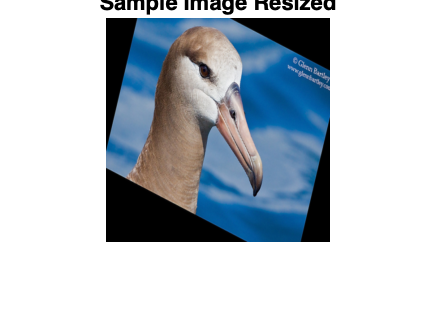

targetSize = [224, 224];

% Data augmentation
augmenter = imageDataAugmenter( ...
    'RandXTranslation',[-20 20], ...
    'RandYTranslation',[-20 20], ...
    'RandRotation',[-20,0], ...
    'RandScale',[0.8,1.2]);
    
augmentedTrainingImageDS = augmentedImageDatastore(targetSize, trainingImageDS, 'DataAugmentation', augmenter, 'OutputSizeMode', 'resize');

% Resize validation and test datastores
validationImageDS_Resized = augmentedImageDatastore(targetSize, validationImageDS, 'OutputSizeMode', 'resize');
testImageDS_Resized = augmentedImageDatastore(targetSize, testImageDS, 'OutputSizeMode', 'resize');

% Display a sample image from the datastore
% Display a sample image from the datastore
figure(1);
sampleImageTable = augmentedTrainingImageDS.read();
sampleImageCell = sampleImageTable{1, 1};
sampleImage = sampleImageCell{1};
imshow(sampleImage);
title('Sample Image Resized');

## Create a simple CNN

layers = [
    imageInputLayer([224 224 3])    % This needs to match the image size
    
    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(20)
    softmaxLayer
    classificationLayer];

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

## Set the training options

options = trainingOptions('sgdm', ...
        'InitialLearnRate', 0.001, ...
        'MiniBatchSize', 20, ...
        'MaxEpochs', 5, ...
        'Verbose', true, ...
        'Shuffle', 'every-epoch', ...
        'VerboseFrequency', 1, ...
        'ValidationData', augmentedTrainingImageDS, ...
        'Plots','training-progress');

## Train the simple CNN model

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |        0.00% |        4.50% |       3.4509 |       4.0939 |          0.0010 |
|       1 |           2 |       00:00:07 |        5.00% |              |       3.7890 |              |          0.0010 |
|       1 |           3 |       00:00:07 |        5.00% |              |       4.5594 |              |          0.0010 |
|       1 |           4 |       00:00:08 |       10.00% |              |       4.2300 |   

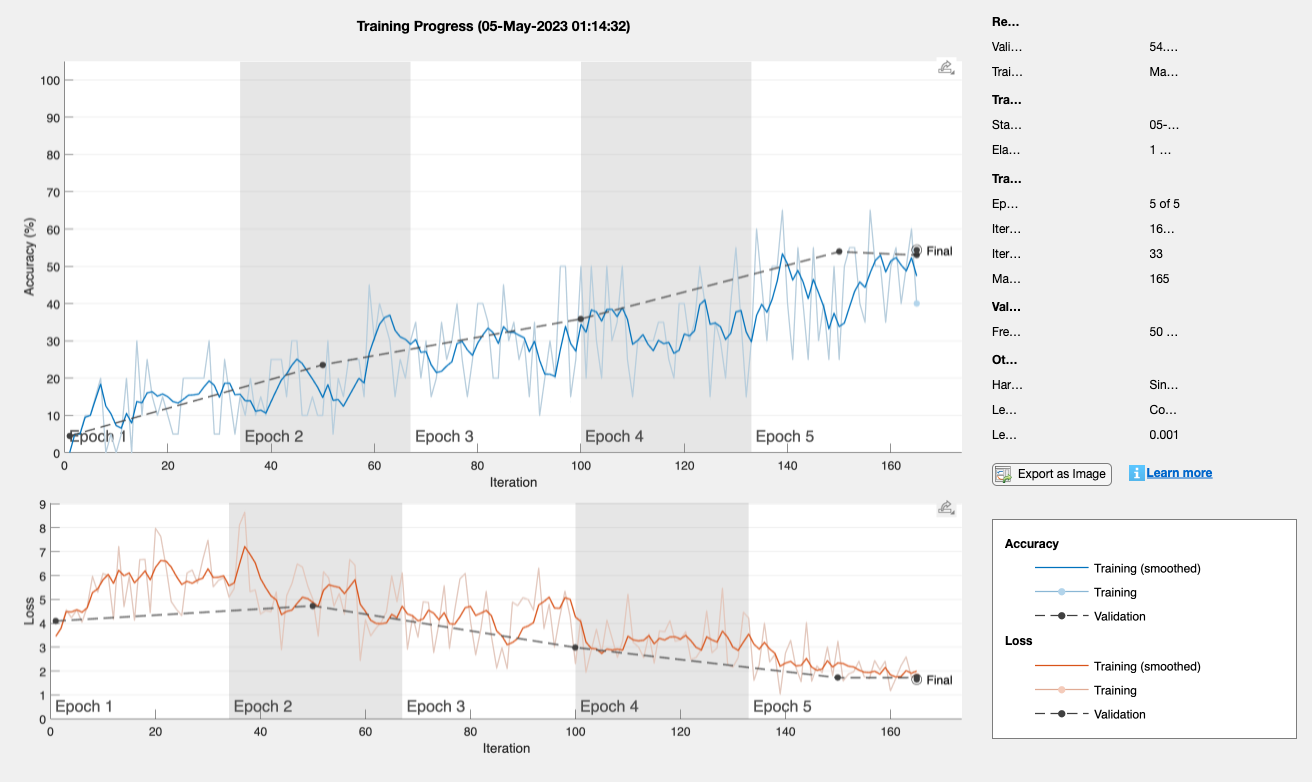

simpleCNN = trainNetwork(augmentedTrainingImageDS, layers, options);

## Test the accuracy on the test partition

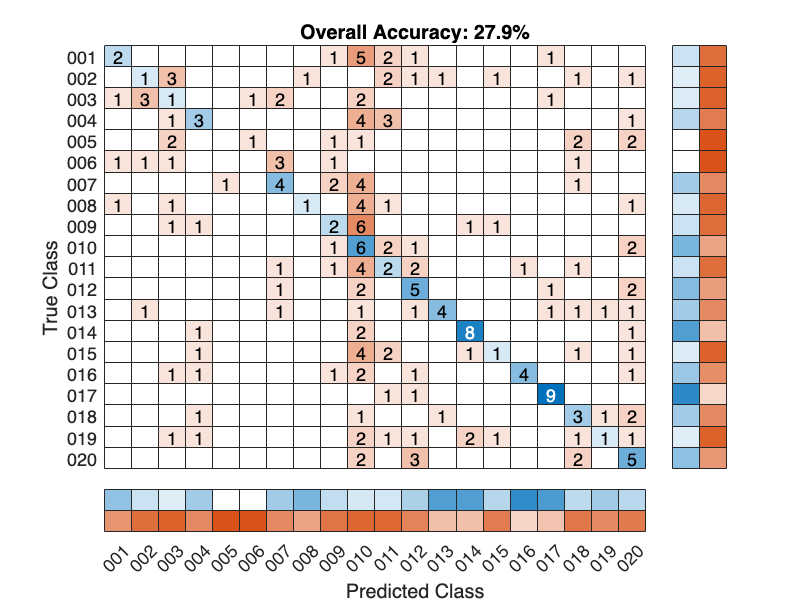

YPred = classify(simpleCNN, testImageDS_Resized);
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest); % Output on command line

% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy: "+ string(round(accuracy*100, 1)) +"%");

## Compute classwise positive recogniton rate

%% Compute classwise positive recogniton rate
classwisePosRecog = cell(height(order), 2);
samplesPerRow = sum(m, 2);
for iI = 1:height(order)
    classwisePosRecog{iI, 1} = order(iI);  % add image name
    classwisePosRecog{iI, 2} = round(100 * m(iI, iI) / samplesPerRow(iI), 1);  % add recognition rate
end
disp('Classwise Recognition Rates:');

Classwise Recognition Rates:


disp(classwisePosRecog);

    {[001]}    {[16.7000]}
    {[002]}    {[ 8.3000]}
    {[003]}    {[ 9.1000]}
    {[004]}    {[     25]}
    {[005]}    {[      0]}
    {[006]}    {[      0]}
    {[007]}    {[33.3000]}
    {[008]}    {[11.1000]}
    {[009]}    {[16.7000]}
    {[010]}    {[     50]}
    {[011]}    {[16.7000]}
    {[012]}    {[45.5000]}
    {[013]}    {[33.3000]}
    {[014]}    {[66.7000]}
    {[015]}    {[ 9.1000]}
    {[016]}    {[36.4000]}
    {[017]}    {[81.8000]}
    {[018]}    {[33.3000]}
    {[019]}    {[ 8.3000]}
    {[020]}    {[41.7000]}

